# EE 451 Homework 8 

# Lisa Jacklin 

# 11/4/2023

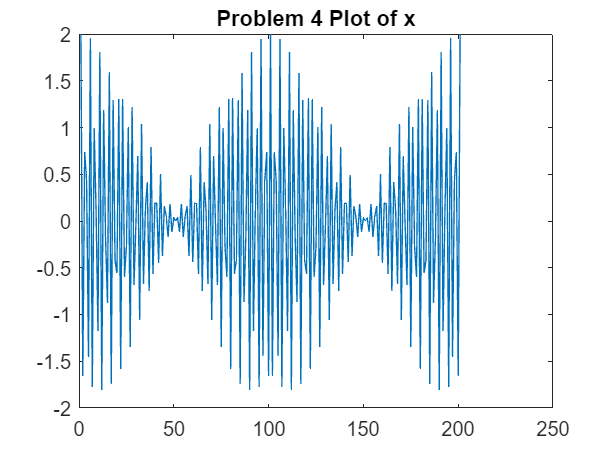

%problem 4
load hw8signal.mat; %this will load in the variable x
%note that this was sampled at 100Hz for 2 seconds.
plot(x);
title("Problem 4 Plot of x");

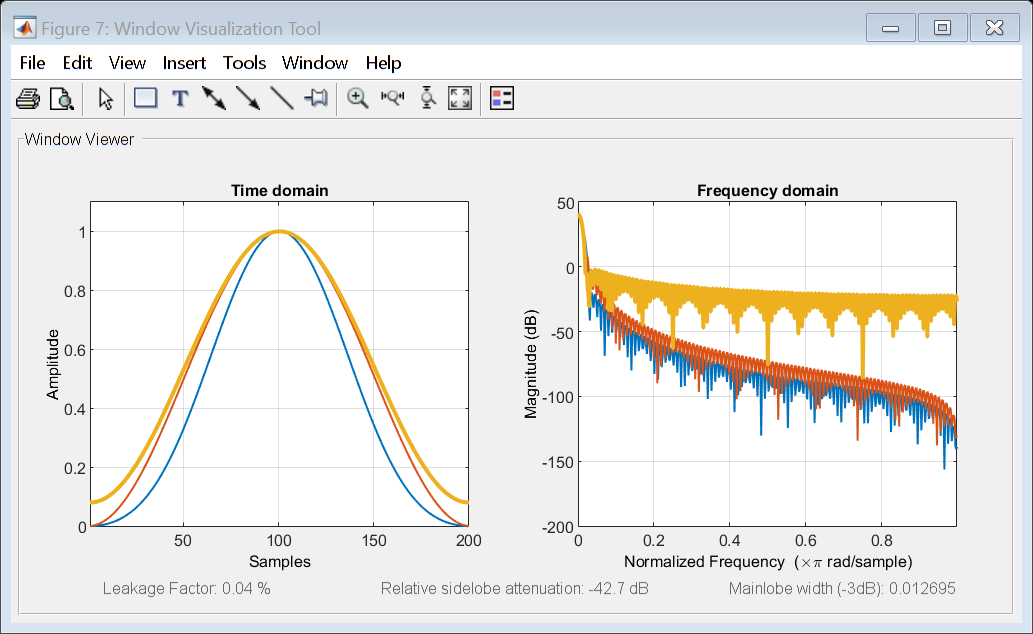


%now, based on the graph, my guess on frequencies prevelent....
%consider the following window functions...
Fs = 100; Ts = 1/Fs;
t = 2;
N = Fs*t;

%now that we have a sample size N, we can take a look at the windowing...
xa = window(@blackman, N);
xb = window(@hanning, N);
xc = window(@hamming, N);
wvtool(xa, xb, xc);

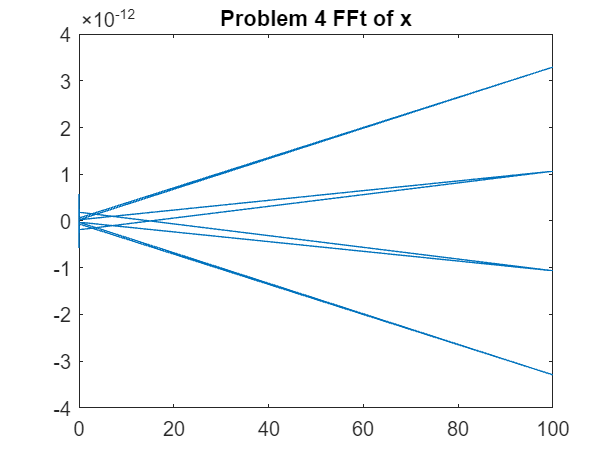

%estimated number of frequency components: 
%

%now, I can go ahead and graph the frequency domain of the signal x
%using fft.

Xf = fft(x, N);
plot(Xf);
title("Problem 4 FFt of x");